data = readtable('../csv/data16.csv');

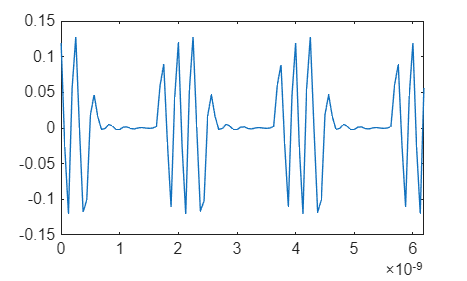

plot(data.time(1:100), data.data(1:100));

% Calculate the 1% and 99% percentiles
lower_bound = prctile(data.data, 1);
upper_bound = prctile(data.data, 99);

% Filter out the 1% maximum and minimum values
filtered_data = data.data(data.data >= lower_bound & data.data <= upper_bound);

% Find Vpp, Vrms, and power
vpp = max(filtered_data) - min(filtered_data);
vrms = vpp / (2 * sqrt(2));
power = (vrms^2) / 50 * 750 / 2000; % assuming the resistance is 50 ohm and 750 / 2000 duty ratio

disp(power);

   6.7901e-05

